## Example

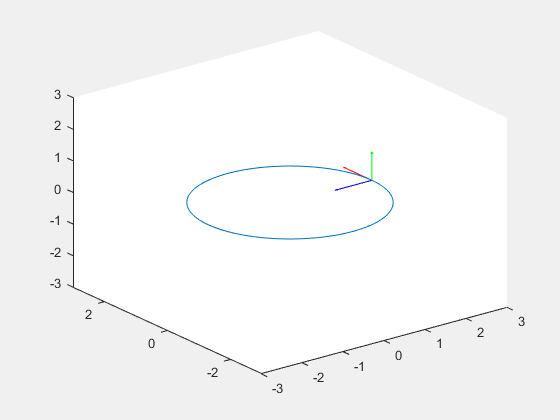

R = 2;% define a specific radius
u = linspace(0,2*pi,100); % define a set of evenly spaced points between 0 and 2*pi
r = [R*cos(u);R*sin(u);0*u];% define the position vector
That = [-sin(u);cos(u);0*u];% define the unit tangent (0*u is easy way to get set of 0's)
Nhat = [-cos(u);-sin(u);0*u];% define the unit normal (0*u is easy way to get set of 0's)
Bhat = [0*u;0*u;1*u./u];% ddefine the unit binormal (1*u/.u is easy way to get set of 1's)
for n = 1:length(u)% loop through each of the points
    plot3(r(1,:),r(2,:),r(3,:)), axis([-3 3 -3 3 -3 3]),hold on % plot the entire curve
    quiver3(r(1,n),r(2,n),r(3,n),That(1,n),That(2,n),That(3,n),'r') % plot the unit tangent
    quiver3(r(1,n),r(2,n),r(3,n),Nhat(1,n),Nhat(2,n),Nhat(3,n),'b') % plot the unit normal
    quiver3(r(1,n),r(2,n),r(3,n),Bhat(1,n),Bhat(2,n),Bhat(3,n),'g'), hold off % plot the unit binormal
    set(gcf,'Visible','on') % force the figure to render external to live script window
    drawnow % force the graphic to update as it goes
end

## 1) Parametric curves

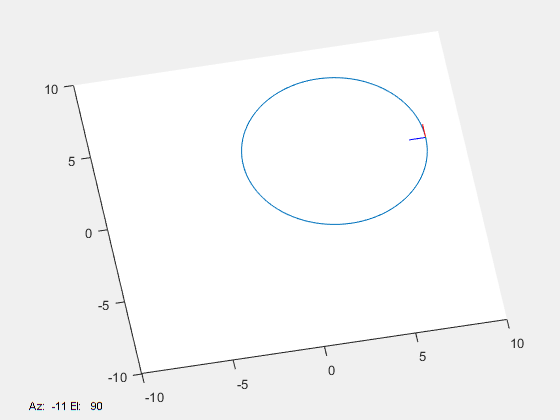

R = 5;% define a specific radius
u = linspace(0,2*pi,100); % define a set of evenly spaced points between 0 and 2*pi
x0 = 3;
y0 = 3;
r = [x0 + R*cos(u);y0 + R*sin(u);0*u];% define the position vector
That = [-sin(u);cos(u);0*u];% define the unit tangent (0*u is easy way to get set of 0's)
Nhat = [-cos(u);-sin(u);0*u];% define the unit normal (0*u is easy way to get set of 0's)
Bhat = [0*u;0*u;1*u./u];% define the unit binormal (1*u/.u is easy way to get set of 1's)
for n = 1:length(u)% loop through each of the points
    plot3(r(1,:),r(2,:),r(3,:)), axis([-10 10 -10 10 -10 10]),hold on % plot the entire curve
    quiver3(r(1,n),r(2,n),r(3,n),That(1,n),That(2,n),That(3,n),'r') % plot the unit tangent
    quiver3(r(1,n),r(2,n),r(3,n),Nhat(1,n),Nhat(2,n),Nhat(3,n),'b') % plot the unit normal
    quiver3(r(1,n),r(2,n),r(3,n),Bhat(1,n),Bhat(2,n),Bhat(3,n),'g'), hold off % plot the unit binormal
    set(gcf,'Visible','on') % force the figure to render external to live script window
    drawnow % force the graphic to update as it goes
end

## 2) Parametric Curves

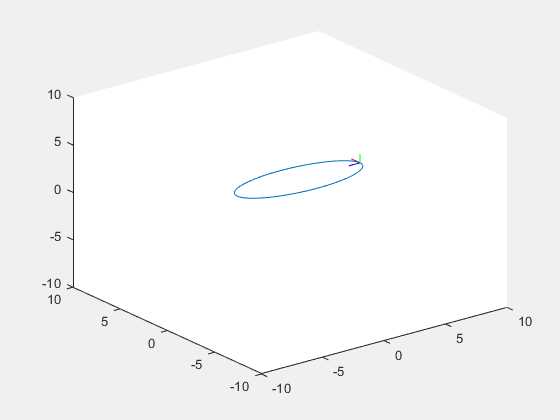

a = 5;% define a specific radius
b = 2;
u = linspace(0,2*pi,100); % define a set of evenly spaced points between 0 and 2*pi
x0 = 3;
y0 = 3;
r = [x0+a*cos(u);y0+b*sin(u);0*u];% define the position vector
That = [(-1).*a.*sin(u).*(b.^2.*cos(u).^2+a.^2.*sin(u).^2).^(-1/2);b.* ...
  cos(u).*(b.^2.*cos(u).^2+a.^2.*sin(u).^2).^(-1/2);0*u];% define the unit tangent (0*u is easy way to get set of 0's)
Nhat = [(-1).*a.*b.^2.*abs(a).^(-1).*abs(b).^(-1).*cos(u).*(b.^2.*cos(u) ...
        .^2+a.^2.*sin(u).^2).^(-1/2);(-1).*a.^2.*b.*abs(a).^(-1).*abs(b) ...
        .^(-1).*sin(u).*(b.^2.*cos(u).^2+a.^2.*sin(u).^2).^(-1/2);0*u];% define the unit normal (0*u is easy way to get set of 0's)
Bhat = [0*u;0*u;a.*b.*abs(a).^(-1).*abs(b).^(-1)*u./u];% define the unit binormal (1*u/.u is easy way to get set of 1's)
for n = 1:length(u)% loop through each of the points
    plot3(r(1,:),r(2,:),r(3,:)), axis([-10 10 -10 10 -10 10]),hold on % plot the entire curve
    quiver3(r(1,n),r(2,n),r(3,n),That(1,n),That(2,n),That(3,n),'r') % plot the unit tangent
    quiver3(r(1,n),r(2,n),r(3,n),Nhat(1,n),Nhat(2,n),Nhat(3,n),'b') % plot the unit normal
    quiver3(r(1,n),r(2,n),r(3,n),Bhat(1,n),Bhat(2,n),Bhat(3,n),'g'), hold off % plot the unit binormal
    set(gcf,'Visible','on') % force the figure to render external to live script window
    drawnow % force the graphic to update as it goes
end

## 3) Parametric Curves

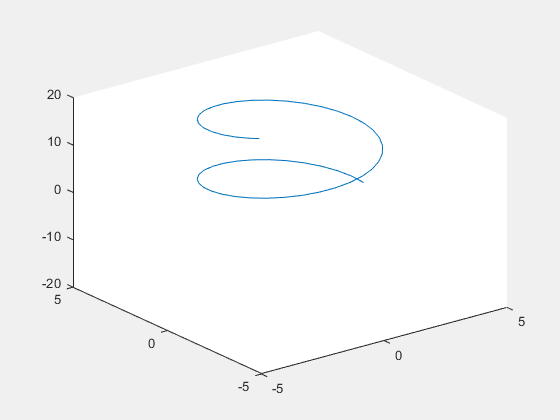

a = 3;% define a specific radius
b = 2;
u = linspace(0,6*pi,100); % define a set of evenly spaced points between 0 and 2*pi
r = [a.*cos(u);a.*sin(u);b.*u];% define the position vector
That = [(-1).*a.*sin(u).*(b.^2+b.^2.*cos(u).^2+a.^2.*sin(u).^2).^(-1/2); ...
        b.*cos(u).*(b.^2+b.^2.*cos(u).^2+a.^2.*sin(u).^2).^(-1/2);b.*( ...
        b.^2+b.^2.*cos(u).^2+a.^2.*sin(u).^2).^(-1/2)]; % define the unit tangent (0*u is easy way to get set of 0's)
Nhat = [(-2).*2.^(1/2).*a.*b.*cos(u).*((3.*a.^2+b.^2+(a.^2+(-1).*b.^2).* ...
        cos(2.*u)).*(b.^2+b.^2.*cos(u).^2+a.^2.*sin(u).^2)).^(-1/2);(-1).* ...
        2.^(1/2).*(a.^2+b.^2).*sin(u).*((3.*a.^2+b.^2+(a.^2+(-1).*b.^2).* ...
        cos(2.*u)).*(b.^2+b.^2.*cos(u).^2+a.^2.*sin(u).^2)).^(-1/2);2.^( ...
        1/2).*((-1).*a.^2+b.^2).*cos(u).*sin(u).*((3.*a.^2+b.^2+(a.^2+(-1) ...
        .*b.^2).*cos(2.*u)).*(b.^2+b.^2.*cos(u).^2+a.^2.*sin(u).^2)).^( ...
        -1/2)];% define the unit normal (0*u is easy way to get set of 0's)
Bhat = [2.^(1/2).*b.*(3.*a.^2+b.^2+(a.^2+(-1).*b.^2).*cos(2.*u)).^(-1/2) ...
  .*sin(u);(-1).*2.^(1/2).*a.*cos(u).*(3.*a.^2+b.^2+(a.^2+(-1).* ...
  b.^2).*cos(2.*u)).^(-1/2);2.^(1/2).*a.*(3.*a.^2+b.^2+(a.^2+(-1).* ...
  b.^2).*cos(2.*u)).^(-1/2)];% define the unit binormal (1*u/.u is easy way to get set of 1's)
for n = 1:length(u)% loop through each of the points
    plot3(r(1,:),r(2,:),r(3,:)), axis([-5 5 -5 5 -20 20]),hold on % plot the entire curve
    quiver3(r(1,n),r(2,n),r(3,n),That(1,n),That(2,n),That(3,n),'r') % plot the unit tangent
    quiver3(r(1,n),r(2,n),r(3,n),Nhat(1,n),Nhat(2,n),Nhat(3,n),'b') % plot the unit normal
    quiver3(r(1,n),r(2,n),r(3,n),Bhat(1,n),Bhat(2,n),Bhat(3,n),'g'), hold off % plot the unit binormal
    set(gcf,'Visible','on') % force the figure to render external to live script window
    drawnow % force the graphic to update as it goes
end

## 4) Motion of Bodies

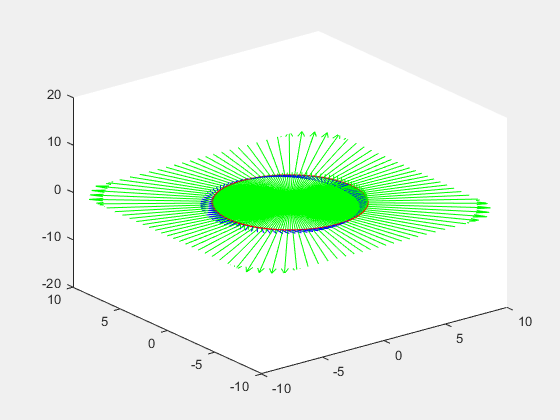

% problem 4 code
a = 5;% define a specific radius
b = 5;
c = 2;
t = linspace(0,2*pi,100); % define a set of evenly spaced points between 0 and 2*pi
r = [a*cos(c*t);b*sin(c*t);0*t];% define the position vector
vel = [(-1).*a.*c.*sin(c.*t);b.*c.*cos(c.*t);0*t];
acc = [(-1).*a.*c.^2.*cos(c.*t);(-1).*b.*c.^2.*sin(c.*t);0*t];
That = [(-1).*a.*sin(c.*t).*(b.^2.*cos(c.*t).^2+a.^2.*sin(c.*t).^2).^( ...
        -1/2);b.*cos(c.*t).*(b.^2.*cos(c.*t).^2+a.^2.*sin(c.*t).^2).^( ...
        -1/2);0*t];% define the unit tangent (0*u is easy way to get set of 0's)
Nhat = [(-1).*b.*cos(c.^2.*t).*((b.^2.*cos(c.^2.*t).^2+a.^2.*sin(c.^2.*t) ...
  .^2).^(-2)).^(1/2).*(b.^2.*cos(c.^2.*t).^2+a.^2.*sin(c.^2.*t).^2) ...
  .^(1/2);(-1).*a.*sin(c.^2.*t).*((b.^2.*cos(c.^2.*t).^2+a.^2.*sin( ...
  c.^2.*t).^2).^(-2)).^(1/2).*(b.^2.*cos(c.^2.*t).^2+a.^2.*sin( ...
  c.^2.*t).^2).^(1/2);0*t];% define the unit normal (0*u is easy way to get set of 0's)
Bhat = [0*t;0*t;2.*((a.^2+b.^2+((-1).*a.^2+b.^2).*cos(2.*c.*t)).*(a.^2+b.^2+( ...
  (-1).*a.^2+b.^2).*cos(2.*c.^2.*t))).^(-1/2).*(b.^2.*cos(c.*t).* ...
  cos(c.^2.*t)+a.^2.*sin(c.*t).*sin(c.^2.*t))];% define the unit binormal (1*u/.u is easy way to get set of 1's)
accthat = [(-1).*a.*sin(c.*t).*(b.^2.*cos(c.*t).^2+a.^2.*sin(c.*t).^2).^( ...
  -1/2).*(a.^2.*c.^2.*cos(c.*t).*sin(c.*t).*(b.^2.*cos(c.*t).^2+ ...
  a.^2.*sin(c.*t).^2).^(-1/2)+(-1).*b.^2.*c.^2.*cos(c.*t).*sin(c.*t) ...
  .*(b.^2.*cos(c.*t).^2+a.^2.*sin(c.*t).^2).^(-1/2));b.*cos(c.*t).*( ...
  b.^2.*cos(c.*t).^2+a.^2.*sin(c.*t).^2).^(-1/2).*(a.^2.*c.^2.*cos( ...
  c.*t).*sin(c.*t).*(b.^2.*cos(c.*t).^2+a.^2.*sin(c.*t).^2).^(-1/2)+ ...
  (-1).*b.^2.*c.^2.*cos(c.*t).*sin(c.*t).*(b.^2.*cos(c.*t).^2+a.^2.* ...
  sin(c.*t).^2).^(-1/2));0*t];
accnhat = [(-1).*b.*cos(c.*t).*(b.^2.*cos(c.*t).^2+a.^2.*sin(c.*t).^2).^( ...
  -1/2).*(a.*b.*c.^2.*cos(c.*t).^2.*(b.^2.*cos(c.*t).^2+a.^2.*sin( ...
  c.*t).^2).^(-1/2)+a.*b.*c.^2.*sin(c.*t).^2.*(b.^2.*cos(c.*t).^2+ ...
  a.^2.*sin(c.*t).^2).^(-1/2));(-1).*a.*sin(c.*t).*(b.^2.*cos(c.*t) ...
  .^2+a.^2.*sin(c.*t).^2).^(-1/2).*(a.*b.*c.^2.*cos(c.*t).^2.*( ...
  b.^2.*cos(c.*t).^2+a.^2.*sin(c.*t).^2).^(-1/2)+a.*b.*c.^2.*sin(c.* ...
  t).^2.*(b.^2.*cos(c.*t).^2+a.^2.*sin(c.*t).^2).^(-1/2));0*t];
for n = 1:length(t)% loop through each of the points
    plot3(r(1,:),r(2,:),r(3,:)), axis([-10 10 -10 10 -20 20]),hold on % plot the entire curve
    quiver3(r(1,n),r(2,n),r(3,n),That(1,n),That(2,n),That(3,n),'r') % plot the unit tangent
    quiver3(r(1,n),r(2,n),r(3,n),Nhat(1,n),Nhat(2,n),Nhat(3,n),'b') % plot the unit normal
    quiver3(r(1,n),r(2,n),r(3,n),Bhat(1,n),Bhat(2,n),Bhat(3,n),'g') % plot the unit binormal
    %quiver3(r(1,n),r(2,n),r(3,n),vel(1,n),vel(2,n),vel(3,n),'r') % plot the unit tangent
    quiver3(r(1,n),r(2,n),r(3,n),accthat(1,n),accthat(2,n),accthat(3,n),'r')
    quiver3(r(1,n),r(2,n),r(3,n),accnhat(1,n),accnhat(2,n),accnhat(3,n),'g')
    %quiver3(r(1,n),r(2,n),r(3,n),acc(1,n),acc(2,n),acc(3,n),'b'), hold off % plot the unit normal
    set(gcf,'Visible','on') % force the figure to render external to live script window
    drawnow % force the graphic to update as it goesfprintf('x is equal to %6.2f.\n',x);
end

## 5) Motion of Bodies

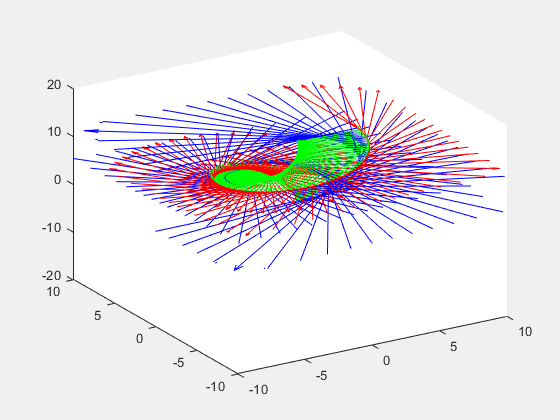

a = 5;% define a specific radius
b = 2;
c = 1;
t = linspace(0,2*pi,100); % define a set of evenly spaced points between 0 and 2*pi
r = [a.*cos(c.*t);a.*sin(c.*t);b.*c.*t];% define the position vector
That = [(-1).*a.*c.*((a.^2+b.^2).*c.^2).^(-1/2).*sin(c.*t);a.*c.*((a.^2+ ...
      b.^2).*c.^2).^(-1/2).*cos(c.*t);b.*c.*((a.^2+b.^2).*c.^2).^(-1/2)*t./t]; % define the unit tangent (0*u is easy way to get set of 0's)
Nhat = [(-1).*a.*c.^2.*(a.^2.*(a.^2+b.^2).^(-1).*c.^2).^(-1/2).*((a.^2+ ...
  b.^2).*c.^2).^(-1/2).*cos(c.*t);(-1).*a.*c.^2.*(a.^2.*(a.^2+b.^2) ...
  .^(-1).*c.^2).^(-1/2).*((a.^2+b.^2).*c.^2).^(-1/2).*sin(c.*t);0*t]; % define the unit normal (0*u is easy way to get set of 0's)
Bhat = [a.^(-1).*b.*c.^(-1).*(a.^2.*(a.^2+b.^2).^(-1).*c.^2).^(1/2).*sin( ...
  c.*t);(-1).*a.^(-1).*b.*c.^(-1).*(a.^2.*(a.^2+b.^2).^(-1).*c.^2) ...
  .^(1/2).*cos(c.*t);c.^(-1).*(a.^2.*(a.^2+b.^2).^(-1).*c.^2).^(1/2)*t./t]; % define the unit binormal (1*u/.u is easy way to get set of 1's)
accthat = [0*t;0*t;0*t];     
accnhat = [(-1).*a.*c.^2.*(a.^2.*(a.^2+b.^2).^(-1).*c.^2).^(-1/2).*((a.^2+ ...
  b.^2).*c.^2).^(-1/2).*cos(c.*t).*(a.^2.*c.^4.*(a.^2.*(a.^2+b.^2) ...
  .^(-1).*c.^2).^(-1/2).*((a.^2+b.^2).*c.^2).^(-1/2).*cos(c.*t).^2+ ...
  a.^2.*c.^4.*(a.^2.*(a.^2+b.^2).^(-1).*c.^2).^(-1/2).*((a.^2+b.^2) ...
  .*c.^2).^(-1/2).*sin(c.*t).^2);(-1).*a.*c.^2.*(a.^2.*(a.^2+b.^2) ...
  .^(-1).*c.^2).^(-1/2).*((a.^2+b.^2).*c.^2).^(-1/2).*sin(c.*t).*( ...
  a.^2.*c.^4.*(a.^2.*(a.^2+b.^2).^(-1).*c.^2).^(-1/2).*((a.^2+b.^2) ...
  .*c.^2).^(-1/2).*cos(c.*t).^2+a.^2.*c.^4.*(a.^2.*(a.^2+b.^2).^(-1) ...
  .*c.^2).^(-1/2).*((a.^2+b.^2).*c.^2).^(-1/2).*sin(c.*t).^2);0*t];
for n = 1:length(t)% loop through each of the points
    plot3(r(1,:),r(2,:),r(3,:)), axis([-10 10 -10 10 -20 20]),hold on % plot the entire curve
    quiver3(r(1,n),r(2,n),r(3,n),That(1,n),That(2,n),That(3,n),'r') % plot the unit tangent
    quiver3(r(1,n),r(2,n),r(3,n),Nhat(1,n),Nhat(2,n),Nhat(3,n),'b') % plot the unit normal
    quiver3(r(1,n),r(2,n),r(3,n),Bhat(1,n),Bhat(2,n),Bhat(3,n),'g') % plot the unit binormal
    quiver3(r(1,n),r(2,n),r(3,n),accthat(1,n),accthat(2,n),accthat(3,n),'r')
    quiver3(r(1,n),r(2,n),r(3,n),accnhat(1,n),accnhat(2,n),accnhat(3,n),'g')
    quiver3(r(1,n),r(2,n),r(3,n),vel(1,n),vel(2,n),vel(3,n),'r') % plot the unit tangent
    quiver3(r(1,n),r(2,n),r(3,n),acc(1,n),acc(2,n),acc(3,n),'b')%, hold off % plot the unit normal
    set(gcf,'Visible','on') % force the figure to render external to live script window
    drawnow % force the graphic to update as it goesfprintf('x is equal to %6.2f.\n',x);
end